# Discrete Fourier Transform

The discrete Fourier transform, or DFT, is the primary tool of digital signal processing. The foundation of the product is the fast Fourier transform (FFT), a method for computing the DFT with reduced execution time.

The MATLAB® environment provides the functions `fft` and `ifft` to compute the discrete Fourier transform and its inverse, respectively. For the input sequence *x* and its transformed version *X* (the discrete-time Fourier transform at equally spaced frequencies around the unit circle)

- Select Time Range (Time Vector)

t = 0:1/100:10-1/100;

- Choose The Signal from drop down;

x = sin(2*pi*15*t) + sin(2*pi*40*t);  

Compute the DFT of the signal and the magnitude and phase of the transformed sequence. Decrease round-off error when computing the phase by setting small-magnitude transform values to zero.

y = fft(x);                               % Compute DFT of x
m = abs(y);                               % Magnitude
y(m<1e-6) = 0;
p = unwrap(angle(y)); 

Plotting Of function in time

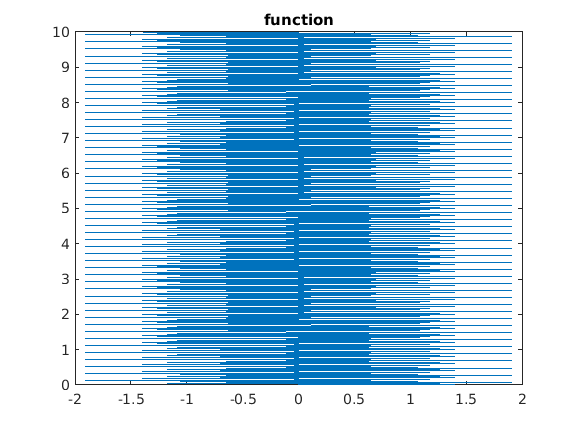

plot(x,t)
title('function')

frequency and phase


f = (0:length(y)-1)*100/length(y);        % Frequency vector

subplot(2,1,1)
plot(f,m)
title('Magnitude')
ax = gca;
ax.XTick = [15 40 60 85];

subplot(2,1,2)
plot(f,p*180/pi)
title('Phase')
ax = gca;
ax.XTick = [15 40 60 85];

 Custom Fourier Transform With Number of points to be sampled

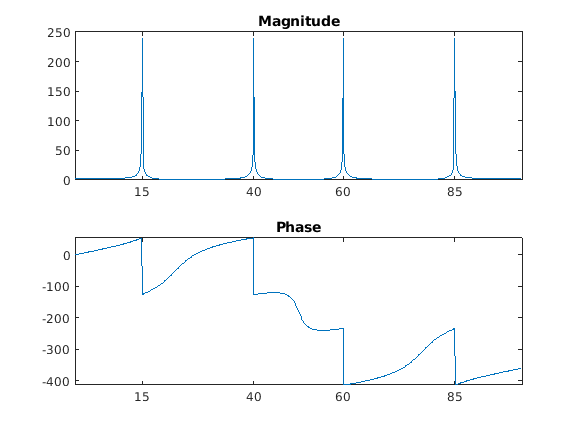

n = 512;
y = fft(x,n);
m = abs(y);
p = unwrap(angle(y));
f = (0:length(y)-1)*100/length(y);

subplot(2,1,1)
plot(f,m)
title('Magnitude')
ax = gca;
ax.XTick = [15 40 60 85];

subplot(2,1,2)
plot(f,p*180/pi)
title('Phase')
ax = gca;
ax.XTick = [15 40 60 85];

In this case, `fft` pads the input sequence with zeros if it is shorter than `n`, or truncates the sequence if it is longer than `n`. If `n` is not specified, it defaults to the length of the input sequence. Execution time for `fft` depends on the length, `n`, of the DFT it performs; see the `fft` reference page for details about the algorithm.

### Measuring Error:

The inverse discrete Fourier transform function `ifft` also accepts an input sequence and, optionally, the number of desired points for the transform. Try the example below; the original sequence `x` and the reconstructed sequence are identical (within rounding error).

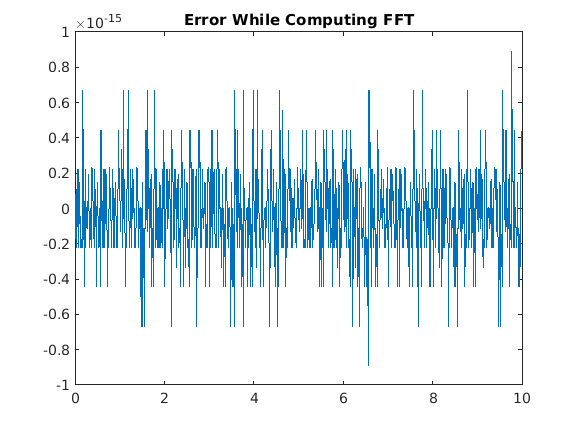

y = real(ifft(fft(x)));

figure
plot(t,x-y)
title("Error While Computing FFT")